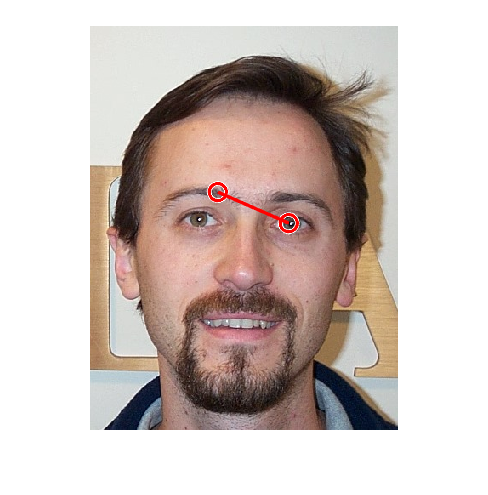

clear
img = imread("../db/DB1/db1_07.jpg");
hybrid_mask = hybrid(img);
hold off

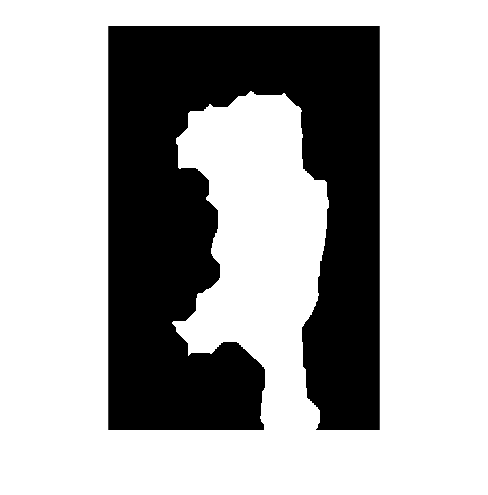


% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)

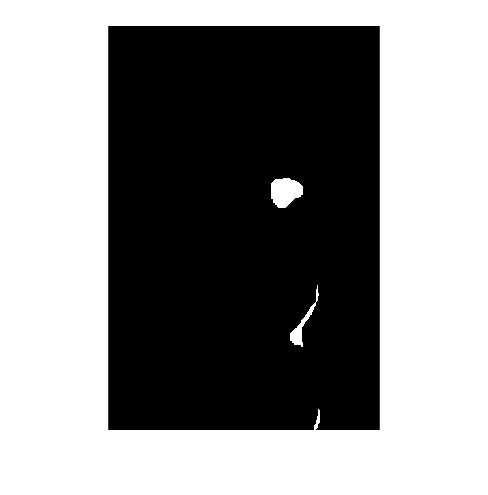


%Find eyes and a mouth
eyes = eyemap(img_gw);
eye_mask = eyemask(eyes,face_mask);

imshow(eye_mask)

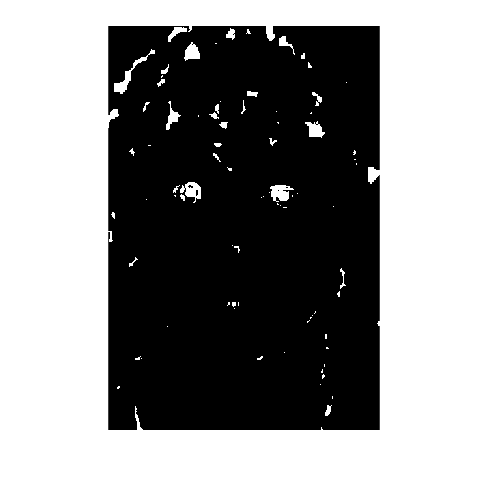

imshow(hybrid_mask)


mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)

[x,y] = mouth_index(mouth_mask);


[indexX,indexY] = eye_index(hybrid_mask)

indexX =     7.8594    4.0000   78.3284   84.5679  100.3855  123.4534  155.9610  161.3333  160.7419  169.9863  180.3179  211.6484  237.6561  241.6250  303.6538  307.6569  322.8762  388.1565


indexY =   131.0885  308.9672   83.1791   65.0617   10.4337   39.5784  132.1818  174.5167  121.0806  145.3425   12.7483   99.7912   11.0860  170.0312  153.1332  104.9510  564.4190  218.0735


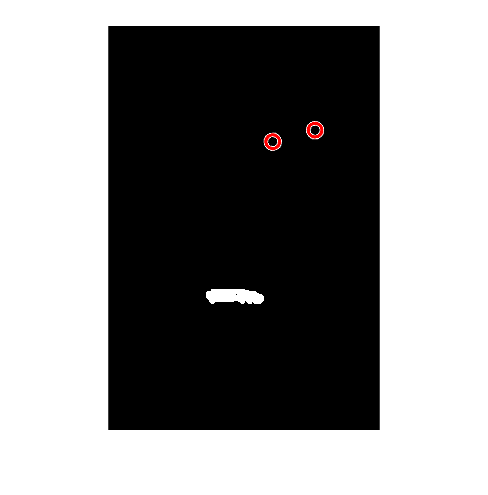

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


eye1 =   303.6538  153.1332


eye2 =   241.6250  170.0312


% [indexX,indexY] = eye_index(eye_mask)
mouth_center = [x, y]; % replace with actual coordinates
[eye1 , eye2] = findEyePair(indexX,indexY,mouth_center)

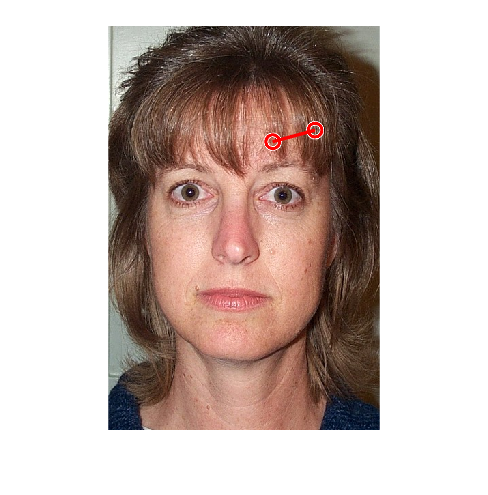


imshow(img)
hold on;
viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r')